# B0_Model_Basics

The model has four equations and 20 parameters. This code package assumes that species are in a certain order as well as parameters are in a certain order.

**State Variables:**

- nAB (non-optimal anaerobic bacteria)

- Li (*L. iners*)

- oLB (*L. crispatus, L. jensenii, L. gasseri*)

- Probiotic strain

**Parameters:**

Parameters are assumed to be a vector of growth rates (in order of start variables) and then a vectorized interspecies interaction matrix.

- kgrow-nAB

- kgrow-Li

- kgrow-oLB

- kgrow-P

- alpha nAB -> nAB

- alpha nAB -> Li

- alpha nAB -> oLB

- alpha nAB -> P

- alpha Li -> nAB

- alpha Li -> Li

- alpha Li -> oLB

- alpha Li -> P

- alpha oLB -> nAB

- alpha oLB -> Li

- alpha oLB -> oLB

- alpha oLB -> P

- alpha P -> nAB

- alpha P -> Li

- alpha P -> oLB

- alpha P -> P

This format of the parameters makes it possible to write functions that can adjust to any number of species. For example, `lhs_ode_gLV`, `symbolic_solns`, and `gLV_jacobian` can all adapt for any number of species generalized Lotka Volterra Model.

Explanation for a 3 species model can be viewed here: [https://github.com/Arnold-Lab-UofM/CST_ODEhttps://github.com/Arnold-Lab-UofM/CST_ODE](https://github.com/Arnold-Lab-UofM/CST_ODEhttps://github.com/Arnold-Lab-UofM/CST_ODE) 

## Example Numerical ODE Call

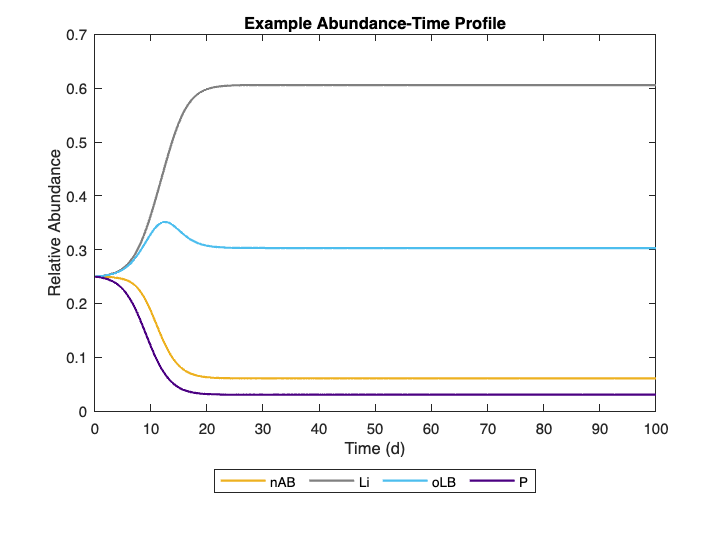

y0 = [0.1 0.1 0.1 0.1]; % initial conditions
params = [0.5 0.5 0.5 0.5 -0.04 0 0 0 0 -0.004 0 0 0 0 -0.008 0 0 0 0 -0.08]; % dummy parameters
odeOptions = odeset('AbsTol',1e-25,'RelTol',1e-10,'Jacobian',@gLV_jacobian); % ode settings
[t,y] = ode15s(@lhs_ode_gLV,[0 100],y0,odeOptions,params); % call numerical solver

% Plot Results
[~,~,sp_cols,~] = get_naming_terms();
plot(t,y./sum(y,2),'LineWidth',1.5);colororder(sp_cols);
ylabel('Relative Abundance');xlabel('Time (d)')
title('Example Abundance-Time Profile'); 
legend({'nAB','Li','oLB','P'},'Location','southoutside','Orientation','horizontal')

## Example Classification to CSTs

The methodology used to classify dominance uses a nearest centroid classifier based on how CSTs are classified in France et al. 2020: [https://microbiomejournal.biomedcentral.com/articles/10.1186/s40168-020-00934-6](https://microbiomejournal.biomedcentral.com/articles/10.1186/s40168-020-00934-6) 

CST_post_names = {'nAB-dominant','Li-dominant','oLB-dominant','P-dominant'}

CST_post_names = 1×4 cell array
    {'nAB-dominant'}    {'Li-dominant'}    {'oLB-dominant'}    {'P-dominant'}



ra = [0.7 0.2 0.1 0]; % nAB-dominanat
ra_class = CST_post_names{get_CST_post(ra)};
disp("A relative abunance of: ")

A relative abunance of: 


disp(num2str(ra,"nAB = %.1f, Li = %.1f, oLB  = %.1f, P =  %.1f" ))

nAB = 0.7, Li = 0.2, oLB  = 0.1, P =  0.0


disp(strcat("Classifies as: ",ra_class))

Classifies as: nAB-dominant



ra = [0.2 0.2 0.6 0]; % oLB-dominant
ra_class = CST_post_names{get_CST_post(ra)};
disp("A relative abunance of: ")

A relative abunance of: 


disp(num2str(ra,"nAB = %.1f, Li = %.1f, oLB  = %.1f, P =  %.1f" ))

nAB = 0.2, Li = 0.2, oLB  = 0.6, P =  0.0


disp(strcat("Classifies as: ",ra_class))

Classifies as: oLB-dominant



ra = [0.2 0.2 0.1 0.5]; % P-dominant
ra_class = CST_post_names{get_CST_post(ra)};
disp("A relative abunance of: ")

A relative abunance of: 


disp(num2str(ra,"nAB = %.1f, Li = %.1f, oLB  = %.1f, P =  %.1f" ))

nAB = 0.2, Li = 0.2, oLB  = 0.1, P =  0.5


disp(strcat("Classifies as: ",ra_class))

Classifies as: P-dominant
